# Ecuaciones de segundo orden

# Problemas de valor inicial

## Sistema de dos ecuaciones lineales de primer orden


$$y_1^{\prime } =-0\ldotp 5y_1$$
                        
$$y_1 \left(0\right)=4$$



$$y_2^{\prime } =4-0\ldotp 3y_2 -0\ldotp 1y_1$$
       
$$y_2 \left(0\right)=6$$


Grafica la solución entre t=0 y t=2.

## Sistema de dos ecuaciones lineales **homogeneas** de primer orden

### Matriz M de coeficientes (constantes)

#### Sistema 1

% y' = 3*y-2*z     y(0)=1
% z' = 2*y-2*z     z(0)=-1
f = @(t, yz) [3*yz(1) - 2*yz(2); 2*yz(1) - 2*yz(2)];
tspan = [0 2];
yz0 = [1; -1];
[t, y] = odeRK4(f, yz0, tspan, 0.01);
plot(t, y(1, :))
hold on
plot(t, y(2, :))
legend('y','z','Location','best')
hold off

% (yz)' = f(y,z)
M =[3 -2; 2 -2];
f = @(t, yz) M*yz;
[t, y] = odeRK4(f, yz0, tspan, 0.01);
plot(t, y(1, :))
hold on
plot(t, y(2, :))
legend('y','z','Location','best')
hold off

#### Sistema 2

% y' =  y+z     y(0)=0.1
% z' = -y+z     z(0)=0.2
% tf = 10
syms y(t) t s
f = diff(y, t, 2) + diff(y, t, 2) - 2*y;
laplace(f, t, s)

#### Sistema 3

% y' = -y-6*z     y(0)=0
% z' = 3*y+5*z    z(0)=2
% tf = 10

#### Sistema 4

% y' = -2*y + 5*exp(-t)
% z' = -(y*z^2)/2;
% yz(0) = [2; 4];
% tf = 0.4

#### Sistema 5

Pb 25.26 Chapra

Suponga que un proyectil se lanza hacia arriba desde la superficie de la Tierra. Se acepta que la única fuerza que actúa sobre el objeto es la fuerza de la gravedad, hacia abajo. En estas condiciones, se usa un balance de fuerza para obtener,


$$v^{\prime } =-g\frac{R^2 }{{\left(R+y\right)}^2 }$$


donde v = velocidad hacia arriba (m/s), t = tiempo (s), y = altitud (m) medida hacia arriba a partir de la superficie terrestre, g =aceleración gravitacional a la superficie terrestre (≈9.81 m/$s^2$), y R = radio de la tierra (≈6.37 × ${10}^6$ m). Determine la altura máxima que se obtendría si v(t = 0) = 1 400 m/s.

% y' = v

#### Sistema 6

Pb 20.18 Chapra

The reaction A → B takes place in two reactors in series. The reactors are well mixed but are not at steady state. The unsteady-state mass balance for each stirred tank reactor is shown below:


$$\frac{\mathrm{d}}{\mathrm{d}t}{\textrm{CA}}_1 =\frac{1}{\tau }\left({\textrm{CA}}_0 -{\textrm{CA}}_1 \right)-k\;{\textrm{CA}}_1$$



$$\frac{\mathrm{d}}{\mathrm{d}t}{\textrm{CB}}_1 =-\frac{1}{\tau }{\textrm{CB}}_1 +k\;{\textrm{CA}}_1$$



$$\frac{\mathrm{d}}{\mathrm{d}t}{\textrm{CA}}_2 =\frac{1}{\tau }\left({\textrm{CA}}_1 -{\textrm{CA}}_2 \right)-k\;{\textrm{CA}}_2$$



$$\frac{\mathrm{d}}{\mathrm{d}t}{\textrm{CB}}_2 =\frac{1}{\tau }\left({\textrm{CB}}_1 -{\textrm{CB}}_2 \right)+k\;{\textrm{CA}}_2$$


where 

CA0 = concentration of A at the inlet of the first reactor,

CA1 = concentration of A at the outlet of the first reactor (and inlet of the second), 

CA2 = concentration of A at the outlet of the second reactor, 

CB1 = concentration of B at the outlet of the first reactor (and inlet of the second), 

CB2 = concentration of B in the second reactor, 

$\tau$ = residence time for each reactor, and

 k = the rate constant for reaction of A to produce B. 

If CA0 is equal to 20, find the concentrations of A and B in both reactors during their first 10 minutes of operation. 

Use k = 0.12/min and $\tau$ = 5 min and assume that the initial conditions of all the dependent variables are zero.

$$ans = 2\,s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-2\,\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)-2\,s\,y\left(0\right)-2\,\mathrm{laplace}\left(y\left(t\right),t,s\right)$$

#### Sistema 7

Predator - prey equations

[https://en.wikipedia.org/wiki/Lotka%E2%80%93Volterra_equations](https://en.wikipedia.org/wiki/Lotka%E2%80%93Volterra_equations)

The Lotka-Volterra equations, also known as the predator-prey equations, are a pair of first-order, nonlinear, differential equations frequently used to describe the dynamics of biological systems in which two species interact, one as a predator and the other as prey. 

The populations change through time according to the pair of equations (p1 prey, p2 predator):

                   
$$\frac {\mathrm{d}p_1} {dt} = \alpha*p_1 - \beta * p_1* p_2
\\ \frac {\mathrm{d}p_2} {dt} = \delta * p_1 * p_2  -\gamma * p_2$$


where t is time, $\alpha$ is the natural growth rate of preys (rabbits), $\gamma$ is the natural death rate of predators (foxes), $\beta$ is the death rate of preys per one unit of the predator population, and $\delta$ is the growth rate of predators per one unit of the prey population.

Otros datos

Si usamos Euler y h=0.1, el circuito no se cierra! Si h=0.01, casi se cierra. Si h=0.001, se cierra.

% y1' = 0.25*y1 - 0.01*y1*y2        y1(0) = 80
% y2' = -y2 + 0.01*y1*y2            y2(0) = 30

Otros datos

% y1' = 1.2*y1 - 0.6*y1*y2          y1(0) = 2
% y2' = -0.8*y2 + 0.3*y1*y2         y2(0) = 1

#### Sistema 8


$$\frac{\mathrm{d}}{\mathrm{d}t}x=-y$$
          
$$x\left(0\right)=r$$



$$\frac{\mathrm{d}}{\mathrm{d}t}y=x$$
            
$$y\left(0\right)=0$$


%

#### Sistema 9

The equations


$$\frac{\mathrm{d}}{\mathrm{d}t}x=-\frac{2x}{\sqrt{x^2 +y^2 }}$$
          
$$\frac{\mathrm{d}}{\mathrm{d}t}y=1-\frac{2y}{\sqrt{x^2 +y^2 }}$$


describe the path of a duck attempting to swim across a river by aiming steadily at the target position T. The speed of the river (in the positve y direction) is 1 and ther duck's speed is 2. The duck starts at S, so that $x\left(0\right)=1$and $y\left(0\right)=0$. The target location is (0,0).

Plot the duck's path.

How long does it take the duck to reach the targer?

#### Sistema 10

Find the solution to

$\frac{\mathrm{d}}{\mathrm{d}t}x=-\left(x+y\right)$ and $\frac{\mathrm{d}}{\mathrm{d}t}y=x-y$

passing through (1, 0) in the time interval [0, 10].

Plot the solution x(t) and y(t)

The equations represent a physical situation in which the time variable does not occur explicitly but only implicitly through the dependence of x and y on t and so describes a self-governing or autonomous system.

Plot the trajectory x vs. y of the solution. 

Observe that in the figure, the trajectory "spirals" into the origin (0, 0), which is an equilibrium or fixed point for the system. The equilibrium or fixed points are points in the phase plane where the system remains unchanged so that dx/dt = 0 and dy/dt = 0 at such a point.

#### Sistema 11

A phase-locked loop or phase lock loop (**PLL**) is a control system that generates an output signal whose phase is related to the phase of an input signal. There are several different types; the simplest is an electronic circuit consisting of a variable frequency oscillator and a phase detector in a feedback loop. The oscillator's frequency and phase are controlled proportionally by an applied voltage, hence the term voltage-controlled oscillator (VCO). The oscillator generates a periodic signal of a specific frequency, and the phase detector compares the phase of that signal with the phase of the input periodic signal, to adjust the oscillator to keep the phases matched. Keeping the input and output phase in lockstep also implies keeping the input and output frequencies the same. Consequently, in addition to synchronizing signals, a phase-locked loop can track an input frequency, or it can generate a frequency that is a multiple of the input frequency. These properties are used for computer clock synchronization, demodulation, and frequency synthesis. [https://en.wikipedia.org/wiki/Phase-locked_loop](https://en.wikipedia.org/wiki/Phase-locked_loop).

Consider a **nonlinear** state equation describing the behavior of a PLL circuit depicted in the next fiigure

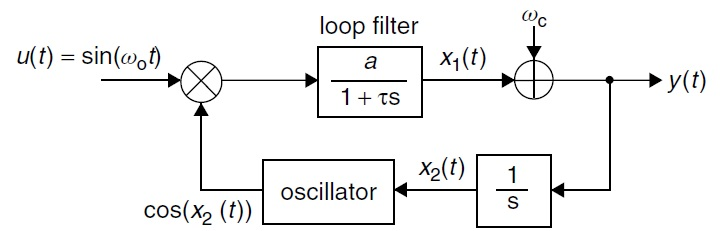


$$\frac{\mathrm{d}}{\mathrm{d}t}x_1 =\frac{a\;u\left(t\right)\;\cos \left(x_2 \left(t\right)\right)-x_1 \left(t\right)}{\tau }$$



$$\frac{\mathrm{d}}{\mathrm{d}t}x_2 =x_1 \left(t\right)+\omega_c$$



$$y\left(t\right)=x_1 \left(t\right)+\omega_c$$


with $a=1500,\tau =0\ldotp 002,u\left(t\right)=\sin \left(\omega_0 t\right)$

where $\omega_0$ = 2100π [rad/s] and $\omega_c$ = 2000π [rad/s]. 

Solve this equation for the time interval [0,0.03]. 

Let the initial condition be [x1(0) x2(0)] = [0 0]. 

Is the output$y\left(t\right)$ tracking the frequency $\omega_0$ of the input $u\left(t\right)$?

## Ecuación diferencial lineal homogenea de segundo orden

Con coeficientes constantes


$$y^{\textrm{''}} +ay^{\prime } +\textrm{by}=0$$


Se convierte a un sistema de dos ecuaciones diferenciales de primer orden definiendo una nueva variable $z=y^{\prime }$


$$\begin{array}{l}
y^{\prime } =z\\
z^{\prime } =y^{\textrm{''}} =-b\;y\;\;-\;a\;z
\end{array}$$



$$M=\left\lbrack \begin{array}{cc}
0 & 1\\
-b & -a
\end{array}\right\rbrack$$



$${\left\lbrack \begin{array}{c}
y\\
z
\end{array}\right\rbrack }^{\prime } =M\left\lbrack \begin{array}{c}
y\\
z
\end{array}\right\rbrack$$


#### Segundo orden 1

$y^{\prime \prime } +y^{\prime } -2y=0$         $y\left(0\right)=3$, $y^{\prime } \left(0\right)=0$

#### Segundo orden 2

$y^{\prime \prime } -y^{\prime } -2y=0$         $y\left(0\right)=0\ldotp 1$, $y^{\prime } \left(0\right)=0\ldotp 2$

#### Segundo orden 3

$y^{\prime \prime } +y^{\prime } -6y=0$         $y\left(0\right)=5$, $y^{\prime } \left(0\right)=0$

#### Segundo orden 4

Harmonic oscillator

$y^{\prime \prime } +y=0$         $y\left(0\right)=4$, $y^{\prime } \left(0\right)=0$

% tf = 10;
% y' = z
% z' = -y

#### Segundo orden 5

Motion of a mass connected to a spring, with viscous friction on the surface and an applied external force.

${3y}^{\prime \prime } +{18y}^{\prime } +102y=10$         $y\left(0\right)=0$, $y^{\prime } \left(0\right)=0$

% tf = 5

#### Segundo orden 6

Resuelve el problema siguiente de t=0 a 5.

$y^{\prime \prime } +{0\ldotp 6y}^{\prime } +8y=0$         $y\left(0\right)=4$, $y^{\prime } \left(0\right)=0$

#### Segundo orden 7

Se trata del oscilador de van der Pol (con amortiguamiento no lineal)


$$\frac{d^2 }{\mathrm{d}t^2 }y-\left(1-y^2 \right)\frac{\mathrm{d}}{\mathrm{d}t}y+y=0$$
          
$$y\left(0\right)=y^{\prime } \left(0\right)=1$$


Grafica la solución entre t=0 y t=10.

#### Segundo orden 8

Se trata de la ecuación de Bessel de orden $\nu =1/2$.


$$t^2 \frac{d^2 }{\mathrm{d}t^2 }y+t\frac{\mathrm{d}}{\mathrm{d}t}y+\left(t^2 -\nu^2 \right)y=0$$
          
$$y\left(0\right)=0;y^{\prime } \left(0\right)=1$$


Grafica la solución entre t=0 y t=10.

#### Segundo orden 9

Se trata de la ecuación de Airy (o Stokes).


$$\frac{d^2 }{\mathrm{d}t^2 }y-t\;y=0$$
          
$$y\left(0\right)=1;y^{\prime } \left(0\right)=0$$


Grafica la solución entre t=0 y t=5.

#### Segundo orden 10

The equations


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }r=\frac{9}{r^3 }-\frac{2}{r^2 }$$
       
$$\frac{\mathrm{d}}{\mathrm{d}t}\theta =\frac{3}{r^2 }$$


describe the Newtonian orbit of a particle in an inverse square gravitational field, after suitable choices of some physical constants. If $t=0$ at the position minimum $r$ and


$$r\left(0\right)=3,r^{\prime } \left(0\right)=0,\;\;\theta \left(0\right)=0$$


Plot the orbit of the particle (x,y) from $t=0$ to $t=66$.

#### Segundo orden 11

Consider the IVP

$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }y=-{\left(\frac{\mathrm{d}}{\mathrm{d}t}y\right)}^2 t$,     $y\left(-1\right)=0,y^{\prime } \left(-1\right)=1$

The solution of this IVP at t = 1 is y(1) = π. Solve this problem using the Runge-Kutta method of order 4. Output the absolute error in approximating y(1) = π with h = 0.1, 0.01, and h = 0.001.

#### Segundo orden 12

Solve the second-order differential equation

$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }y-\frac{\mathrm{d}}{\mathrm{d}t}y\;e^y +\;t\;y=t^2$,     y(1) = 0, y′(1) = 1

on the interval [1, 2].

#### Segundo orden 13

Cantilever Beam: Consider a nonlinear state equation describing the vertical deflection of a beam  due to its own weight


$$\textrm{JE}\frac{{\mathrm{d}}^2 }{\mathrm{d}x^2 }y=-\rho \;g\;{\left(1+\frac{\mathrm{d}}{\mathrm{d}x}y\right)}^2 \left\lbrace x\left(x-\frac{L}{2}\right)+\frac{L^2 }{2}\right\rbrace$$


where $\textrm{JE}=2000\;\textrm{kg}\;\frac{m^3 }{s^2 }$, $\rho =10\;\frac{\textrm{kg}}{m}$, $g=9\ldotp 8\;\frac{m}{s^2 }$, $L=2\;m$.

Solve this equation for the interval [0,L] and plot y(t). 

Cantilever beams have one end fixed, so that the slope and deflection at that end must be zero:

Let the initial condition be [y(0) y'(0)] = [0 0]. 

#### Ecuación de tercer orden

Resuelve la ecuación 


$$\frac{{\mathrm{d}}^3 }{\mathrm{d}t^3 }x+x=0$$


con las condiciones iniciales $x^{\prime \prime } \left(0\right)=0,{\;x}^{\prime } \left(0\right)=1,\;x\left(0\right)=0$.

Grafica x(t) en el intervalo [0 , 10] .

Solución simbólica

Solución numérica con rk4 y h=0.5.


$$x^{\prime } =y$$



$$y^{\prime } =z$$



$$z^{\prime } =-x$$


xyz=$\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack$

#### Ecuación lineal homogénea de tercer orden con coeficientes constantes


$$\frac{{\mathrm{d}}^3 }{\mathrm{d}x^3 }y-2\frac{{\mathrm{d}}^2 }{\mathrm{d}x^2 }y-\frac{\mathrm{d}}{\mathrm{d}x}y+2y=0$$


lambda = sort(roots([1,-2,-1,2]))

Como las raíces son distintas, la solución general es de la forma


$$y=c_1 e^{-1x} +c_2 e^{1x} +c_3 e^{2x}$$


% Matriz M

#### Ecuación lineal no homogénea de tercer orden con coeficientes constantes

y′′′(t) + 3y′′(t) + 3y′(t) + y(t) = −4 sin(t),

y(0) = y′(0) = 1, y′′(0) = −1

#### More problems (Kendall Atkinson, Weimin Han, David Stewart)

y′′′(t) + 4y′′(t) + 5y′(t) + 2y(t) = 2t^2 + 10t + 8

y(0) = 1, y′(0) = −1, y′′(0) = 3.

y′′(t) + 4y′(t) + 13y(t) = 40 cos(t),

y(0) = 3, y′(0) = 4.